# Artifact rejection

## **Introduction**

We will show here how trials with artifacts can be identified and then rejected for further processing. 

The aim of MEG research is to characterise the brain activity associated with a given task. Applying MaxFilter greatly attenuates environmental and sensor noise, however various non-brain related artefacts created by the subject as well as line noise still need to be addressed.  

The body related artefacts are primarily  

-  Head movements

-  Eye blinks

-  Saccades

-  Cardiac artefacts; i.e. electrical field generated by the heart 

-  Belt or bras with metal resulting in breathing artefacts

-  Piercings and make-up with metal (some mascara)

-  Dental work involving metal e.g. tooth fillings or braces 

-  Muscle contractions resulting in broadband activity

It is not possible to completely remove these artifacts but a lot can be done to reduce their impact. To attenuate remaining artifacs the main strategies are 1) removing trials with artifacts and 2) using temporal (e.g. notch filters) or spatial filters (e.g. ICA). 

As part of the preprocessing, the data will be corrected for mean amplitude differences across trial and then trials/sensors with large artifacts will be removed. These steps are important to perform prior applying ICA for further artifact attenuation (see next section). 

## **Preparation**

Initialize FiedTrip. 

ft_defaults

Set the path and the file names of the fif files. We will be using the MaxFiltered data.

data_path = 'C:\YOUR_DATA_FOLDER\';

## **Reading the data and filtering in planar gradiometers**

We will first read in the trials using the tools from the previous  section. Remember however that the recording is in two different datafiles. So first specify the MaxFiltered datafiles: 

dataset{1,1}='training_rawsss-1.fif';
dataset{1,2}='training_rawsss-2.fif';

We will call 'ft_preprocessing' but now with each datafile and correcting for mean amplitude difference across trials (cfg.demean). In addition we will focus on the planar gradiometers only so we will restrict the channels to the gradiometers ('MEGGRAD').   

for i=1:length(dataset)
    cfg  = [];
    cfg.dataset = [data_path,char(dataset{1,i})];  
    cfg.trialfun = 'ft_trialfun_general';  
    cfg.trialdef.eventtype  = 'STI101';  
    cfg.trialdef.eventvalue = [21 22];  
    cfg.trialdef.prestim = 2.5;  
    cfg.trialdef.poststim = 2;  
    cfg  = ft_definetrial(cfg);   
    cfg.channel = {'MEGGRAD'};  
    cfg.demean = 'yes';    
    data{i,1}  = ft_preprocessing(cfg); 
end

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif'
	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif ...
Opening raw data file C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif...
	Range : 208000 ... 1664999  =    208.000 ...  1664.999 secs
Ready.


 In ft_datatype_sens at line 325
 In ft_datatype_sens at line 207
 In ft_datatype_sens at line 180
 In ft_read_header at line 2813
 In ft_trialfun_general at line 96
 In ft_definetrial at line 181

reading the events from 'C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif'
	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_

	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif ...
Opening raw data file C:\Users\ferranto\Downloads\flux_sample\training_rawsss-1.fif...
	Range : 208000 ... 1664999  =    208.000 ...  1664.999 secs
Ready.
processing channel { 'MEG0112' 'MEG0113' 'MEG0122' 'MEG0123' 'MEG0132' 'MEG0133' 'MEG0142' 'MEG0143' 'MEG0212' 'MEG0213' 'MEG0222' 'MEG0223' 'MEG0232' 'MEG0233' 'MEG0242' 'MEG0243' 'MEG0312' 'MEG0313' 'MEG0322' 'MEG0323' 'MEG0332' 'MEG0333' 'MEG0342' 'MEG0343' 'MEG0412' 'MEG0413' 'MEG0422' 'MEG0423' 'MEG0432' 'MEG0433' 'MEG0442' 'MEG0443' 'MEG0512' 'MEG0513' 'MEG0522' 'MEG0523' 'MEG0532' 'MEG0533' 'MEG0542' 'MEG0543' 'MEG0612' 'MEG0613' 'MEG0622' 'MEG0623' 'MEG0632' 'MEG0633' 'MEG0642' 'MEG0643' 'MEG0712' 'MEG0713' 'MEG0722' 'MEG0723' 'MEG0732' 'MEG0733' 'MEG0742' 'MEG0743' 'MEG0812' 'MEG0813' 'MEG0822' 'MEG0823' 'MEG0912' 'MEG0913' 'MEG0922' 'MEG0923' 'MEG0932' 'MEG0933' 'MEG0942' 'MEG0943' 'MEG1012' 'MEG1013' 'MEG1022' '

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif'
	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif ...
Opening raw data file C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
reading the events from 'C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif'
	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif ...
Opening raw data file C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
Reading 1665000 ... 3098999  =   1665.000 ...  3098.999 secs... [done]
Reading 1665000 ... 3098999  =   1665.000 ...  3098.999 secs... [done]
found 4129 events
created 172 trials
the call to "ft_definetrial" took 23 seconds


	306 MEG channel locations transformed
Reading C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif ...
Opening raw data file C:\Users\ferranto\Downloads\flux_sample\training_rawsss-2.fif...
	Range : 1665000 ... 3098999  =   1665.000 ...  3098.999 secs
Ready.
processing channel { 'MEG0112' 'MEG0113' 'MEG0122' 'MEG0123' 'MEG0132' 'MEG0133' 'MEG0142' 'MEG0143' 'MEG0212' 'MEG0213' 'MEG0222' 'MEG0223' 'MEG0232' 'MEG0233' 'MEG0242' 'MEG0243' 'MEG0312' 'MEG0313' 'MEG0322' 'MEG0323' 'MEG0332' 'MEG0333' 'MEG0342' 'MEG0343' 'MEG0412' 'MEG0413' 'MEG0422' 'MEG0423' 'MEG0432' 'MEG0433' 'MEG0442' 'MEG0443' 'MEG0512' 'MEG0513' 'MEG0522' 'MEG0523' 'MEG0532' 'MEG0533' 'MEG0542' 'MEG0543' 'MEG0612' 'MEG0613' 'MEG0622' 'MEG0623' 'MEG0632' 'MEG0633' 'MEG0642' 'MEG0643' 'MEG0712' 'MEG0713' 'MEG0722' 'MEG0723' 'MEG0732' 'MEG0733' 'MEG0742' 'MEG0743' 'MEG0812' 'MEG0813' 'MEG0822' 'MEG0823' 'MEG0912' 'MEG0913' 'MEG0922' 'MEG0923' 'MEG0932' 'MEG0933' 'MEG0942' 'MEG0943' 'MEG1012' 'MEG1013' 'MEG1022' 

Next we will merge the datafiles into one single dataset as they represent the first and the second part of the recording. In addition, we will remove the 'sampleinfo' field of the newly created datafile because it would otherwise cause some confusion later due to the merging of two datafiles. 

cfg = [];
cfg.keepsampleinfo = 'no';
data_planar = ft_appenddata(cfg,data{:})

concatenating over the "rpt" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 1 seconds


data_planar = struct with fields:
        label: {204×1 cell}
    trialinfo: [311×1 double]
         grad: [1×1 struct]
        trial: {1×311 cell}
         time: {1×311 cell}
      fsample: 1000
          cfg: [1×1 struct]


## Artifact rejections in planar gradiometers

Having preprocessed the data, the next step is to detect trials and sensors with large artifacts and remove those prior to running ICA. For this purpose we will use the '[ft_rejectvisual](https://www.fieldtriptoolbox.org/tutorial/visual_artifact_rejection/)' function and will rely on summary statistics of the data to detect artifacts. The aim of this step is to reject trials with excessive noise, i.e. by assessing if they are outliers.

It is worth having 'ft_databrowser' running whilst deciding about what trials/sensors should be removed.

To show a set of representative sensors from the front and in the rim write: 

the input is raw data with 204 channels and 311 trials


 In fixsampleinfo at line 90
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_databrowser at line 329



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_databrowser at line 329

> In fixsampleinfo (line 102)
In 

Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



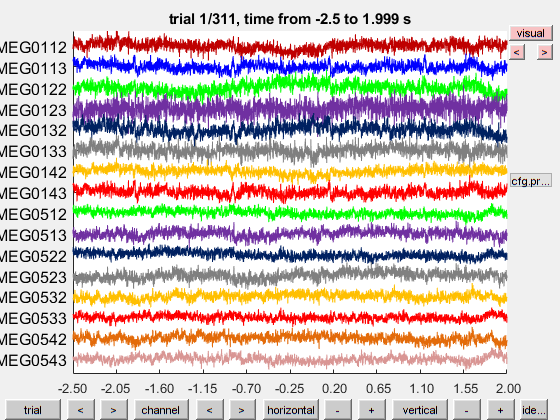

the call to "ft_databrowser" took 5 seconds


cfg = [];
cfg.viewmode='vertical';
cfg.continuous='no';
cfg.ylim=[ -1e-11  1e-11 ];
cfg.channel = {'MEG01*','MEG05*'};  
ft_databrowser(cfg, data_planar);

To plot all of the sensors write: 

the input is raw data with 204 channels and 311 trials


 In fixsampleinfo at line 90
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_databrowser at line 329



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_databrowser at line 329

> In fixsampleinfo (line 102)
In 

Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



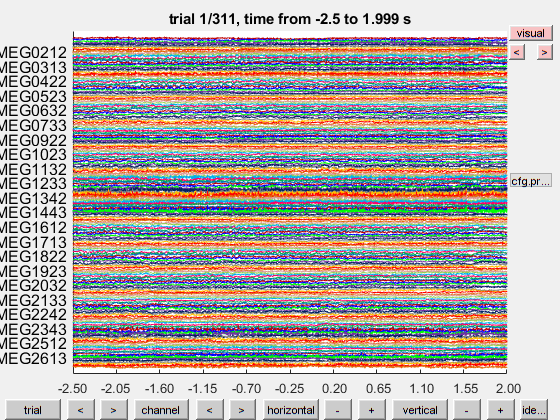

the call to "ft_databrowser" took 4 seconds


cfg = [];
cfg.viewmode='vertical';
cfg.continuous='no';
ft_databrowser(cfg, data_planar);

This will produce an interactive figure with all the planar gradiometer data. Keep the figure on when running 'ft_rejectvisual'. 

### **Question 1**

Browse through the trials. Identify an eyeblink, a muscle artifact and the cardiac heart artifacts (hint; look between trial 50-70). Return plots showing the respective artifacts and briefly explain what characterized them. 

Before doing the visual artifact rejection, run the line below. This will be useful for later bookkeeping as to which trials and channels we keep after this first round of artifact rejection. 

data_planar.trialinfo(1:end,2)=1:length(data_planar.trialinfo);  

To remove particularly noisy trials and/or sensors, one can use statistical properties of the trials and sensors, such as the variance of the data. To do so use 'ft_rejectivisual function' with the 'cfg.method' set as 'summary'. There are a number of statistical properties to be considered. In addition, at this step you should also identify flat or bad sensors for later channel repair. 

cfg=[];
cfg.method  = 'summary';
cfg.layout  = 'neuromag306planar.lay';
planar_rjv1  = ft_rejectvisual(cfg, data_planar);

the input is raw data with 204 channels and 311 trials


 In fixsampleinfo at line 90
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_rejectvisual at line 134



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 148
 In ft_checkdata at line 267
 In ft_rejectvisual at line 134

> In fixsampleinfo (line 102)
In 

computing metric [--|                                                      ]computing metric [---/                                                     ]computing metric [-----                                                    ]computing metric [------\                                                  ]computing metric [-------|                                                 ]computing metric [---------/                                               ]computing metric [-----------                                              ]computing metric [------------\                                            ]computing metric [-------------|                                           ]computing metric [---------------/                                         ]computing metric [-----------------                                        ]computing metric [-----------------\                                       ]computing metric [-------------------|                                     ]computing me

after GUI interaction: 311 trials marked to INCLUDE, 0 trials marked to EXCLUDE
after GUI interaction: 204 channels marked to INCLUDE, 0 channels marked to EXCLUDE
the call to "ft_selectdata" took 0 seconds
the call to "ft_rejectvisual" took 38 seconds


With the variance option ticked the figure shows that a couple of trials (bottom left sub-figure) have considerably larger variance than the rest and the same is true for a few sensors (top right plot).  

The noisiest trial is 99. Entering '99' in the 'Plot trial' box (bottom right) makes a topographically arranged sensor plot of trial  99 (bottom left). This allows to select a particular sensor (or more  than one) and inspect  the data more closely. Select the sensor over  (MEG1322) with possibly the largest deflection of the trial to observe the data  of one channel for one trial (bottom right).   

Inspecting the data with 'ft_databrowser' also shows that there is a large amplitude deflection in the signal on most of the channels.  

Remove trial 99 from the dataset by going back to the original  summary statistics figure and dragging the mouse over the particular trial datapoint in the bottom left plot. By doing so the name of the trial number ('99') will appear under the 'Rejected Trials'.  

Removing the trial also changes the sub-plot and it turns out there are a few more trials (141, 118, 123, 124, 130) in close proximity with large noise. However on closer inspection they likely reflect standard eye-movement artifacts which we will deal with later. 

In total we only excluded one trial and all of the channels have been kept for further processing.   

NOTE: in order for Fieldtrip to perform the rejection of the sensors  and create the new structure 'planar_rjv1' press the button 'Quit'.  Furthermore, note that the list of artifactual trials and sensors can be  augmented manually. This can for instance be done after browsing through the trials in 'ft_databrowser' or another data browser. 

After removing this trial we can move on to the next step.  However before doing so we need to complete the bookkeeping of the trials and channels we kept. 

trl_keep=planar_rjv1.trialinfo(1:end,2);
planar_rjv1.trialinfo(:,2)=[];
chan_rej=setdiff(data_planar.label,planar_rjv1.label);
chan_keep=data_planar.label;
chan_keep(find(ismember(data_planar.label(:,1), chan_rej(:,1))))= [];

As a final step it is a good idea to save the variables which contain the channel list and the trial list we want to keep.  

save([data_path,'chan_keep.mat'], 'chan_keep')
save([data_path,'trl_keep.mat'], 'trl_keep')

### **Question 2**

Use some of the other options e.g. maxabs or maxzvalue. What is the effect on the outliers?  

### **Question 3**

What is better to remove bad sensors before bad trials or other way round? 

## **Preregistration and publications**

Describe the filter type, and settings (filter order, cutoff  frequencies) and the padding applied. Also specify if detrending was  performed.  

**Preregistration:** report how rejection of trials and  sensors will be done. For instance by visual inspection and summarysque statistics to remove outliers. Make explicit if this will be done  separately for gradiometers and the magnetometers. Define how trials  with ocular artefacts will be handled. Importantly define the criteria  for rejecting the dataset for a specific subject. For instance this  might be when more than 25% of the trials has to be rejected or if there were serious data quality problems for instance due to dental work, environmental problems or excessive movements.  

**Publications:** report the artifact rejection strategy from  above. Report the average number and standard deviation of numbers of sensors and trials excluded. If bad channels were interpolated, describe how it was done.  

Example:

"The mean amplitude of each trial was removed. After preprocessing the planar gradiometers inspected visually for artifacts and outlier trials and sensors with excessive variance were removed. In  average XX(+/-YY) trials were per subject and ZZ(+/-WW) sensors.  